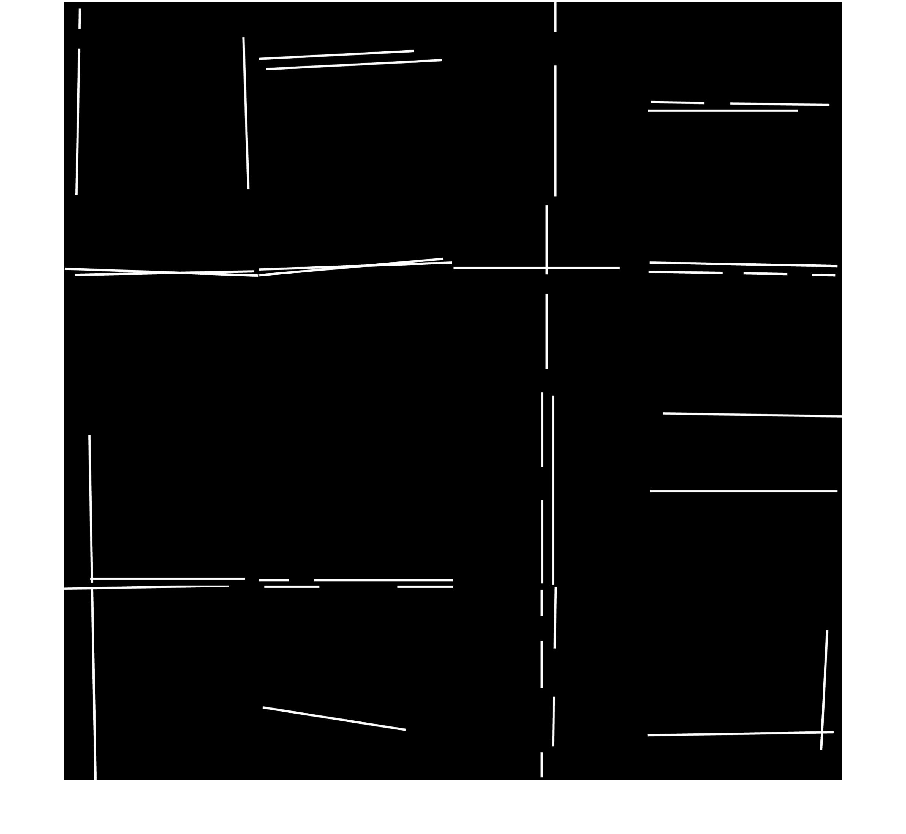

%Reading the result and the ground truth images into the workspace
result=imread('result.jpg');
ground_truth= imread('results/divisions4/field/fieldgt.jpg');

%Resizing the images because they have to be of same size when evaluating
result = imresize(result,[2048 2048]);
ground_truth = imresize(ground_truth, [2048 2048]);

%Converting the images into grayscale images
result=im2gray(result);
ground_truth=im2gray(ground_truth);

%Displaying both the images after modifications.
figure,imshow(result);

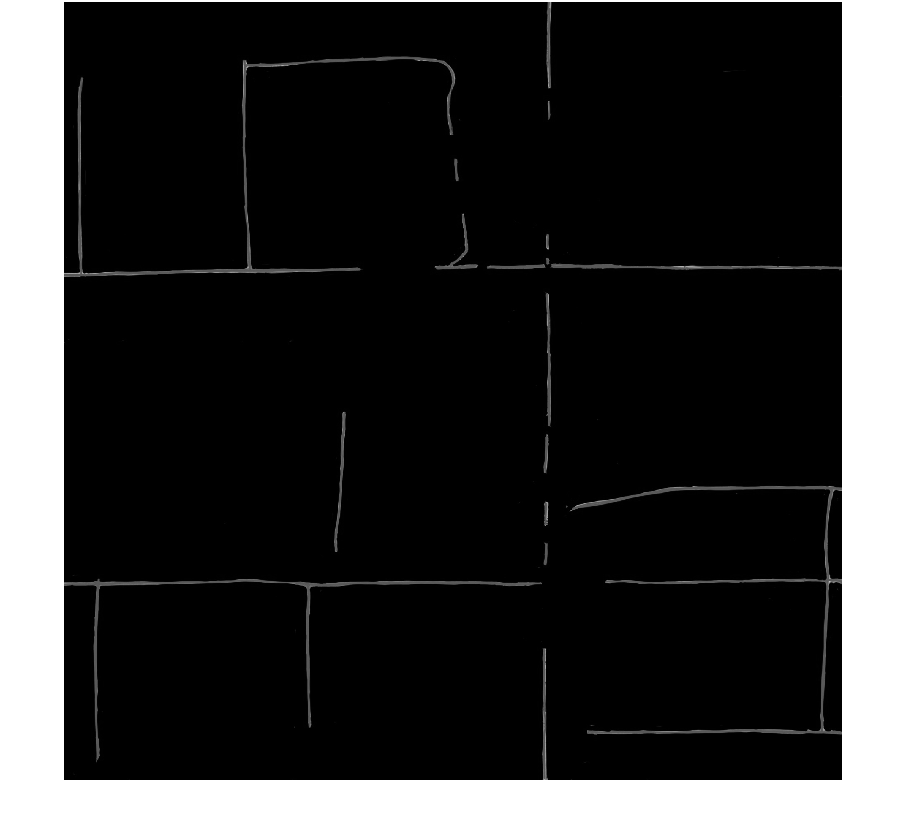

figure,imshow(ground_truth);

%Calling the evaluation function by passing result and the ground_truth
%images as arguments
acc = evaluation(ground_truth,result);

out = struct with fields:
         confusion: [1×1 struct]
       avgAccuracy: 97.0265
           errRate: 2.9735
    precisionMicro: 0.6635
       recallMicro: 44.8035
       fscoreMicro: 1.3077
    precisionMacro: NaN
       recallMacro: NaN
       fscoreMacro: NaN


function [out] = evaluation(targets,outputs)

%Applying confusion function for both the images to get the confusion
%amtrix for both the imaegs
[c,cm,ind,per] = confusion(targets,outputs);
%These are the outputs of the confusion function
%cm is the confusion matrix and we ge the tp,tn,fp,fn from this cm
out.confusion.c = c;
out.confusion.cm = cm;
out.confusion.ind = ind;
out.confusion.per = per;

%Initializing all the variables to 0 to calculate the accuracy, precision,
%recall,and fscore.
nClasses=size(outputs,1);
beta=1;
avgAccuray=0.0;
errRate=0.0;
numeratorP=0.0;
denominatorP=0.0;
numeratorR=0.0;
denominatorR=0.0;
precisionMacro=0.0;
recallMacro=0.0;

%Looping into all the classes that we have in the image and calculating the
%fields 
for i=1:nClasses
    fn=per(i,1);
    fp=per(i,2);
    tp=per(i,3);
    tn=per(i,4);
    

    %Calculating all the fields using the formulaes related to true
    %positives, true negatives, false positives, false negatives.
    avgAccuray=+avgAccuray+((tp+tn)/(tp+fn+fp+tn));
    errRate=+errRate+((fp+fn)/(tp+fn+fp+tn));
    numeratorP=numeratorP+tp;
    denominatorP=denominatorP+ (tp+fp);
    numeratorR=numeratorR+tp;
    denominatorR=denominatorR + (tp+fn);
    precisionMacro=precisionMacro+(tp/(tp+fp));
    recallMacro=recallMacro+(tp/(tp+fn));
end
%Average Accuracy (The average per-class effectiveness of a classifier)
avgAccuray=avgAccuray/nClasses;

%Error Rate (The average per-class classification error)
errRate=errRate/nClasses;

%Precision-Micro (Agreement of the data class labels with those of a
% %classifiers if calculated from sums of per-text decisions)
precisionMicro=numeratorP/denominatorP;
% 
% %Recall-Micro (Effectiveness of a classifier to identify class labels if
% %calculated from sums of per-text decisions)
recallMicro=numeratorR/denominatorR;
% 
% %Fscore-Micro (Relations between data's positive labels and those given by a classifier based on sums of per-text decisions)
fscoreMicro= ((beta^2+1)*precisionMicro*recallMicro)/(beta^2*precisionMicro+recallMicro);
% 
% %Precision-Macro (An average per-class agreement of the data class labels with those of a classifiers)
precisionMacro=precisionMacro/nClasses;
% 
% %Recall-Micro (An average per-class effectiveness of a classifier to identify class labels)
recallMacro=recallMacro/nClasses;
% 
% %Fscore-Macro (Relations between data's positive labels and those given by a classifier based on a per-class average)
fscoreMacro=((beta^2+1)*precisionMacro*recallMacro)/(beta^2*precisionMacro+recallMacro);



%Calculating all the fields for 100% for better understanding of the
%results.
out.avgAccuracy = avgAccuray*100;
out.errRate = errRate*100;
out.precisionMicro = precisionMicro*100;
out.recallMicro = recallMicro*100;
out.fscoreMicro = fscoreMicro*100;
out.precisionMacro = precisionMacro*100;
out.recallMacro = recallMacro*100;
out.fscoreMacro = fscoreMacro*100
end